clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters

param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]


param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


simtime = 10*60;

% param.model.Dg*param.ctrl.Lambda_Bar

% Skriver en diagonal -1 på integralstaten.
% for i=1:4
%     param.model.A(3*i,3*i) = -1;
% end

s = tf('s');
Wdelta = eye(4)*1/(1/0.1*s+1);
% Wdelta = eye(4)*tf([1,0],[1,0]);
WdeltaSS = ss(Wdelta);
param.model.Awd = WdeltaSS.A;
param.model.Bwd = WdeltaSS.B;
param.model.Cwd = WdeltaSS.C;
param.model.Dwd = WdeltaSS.D;

## Control

% [param.ctrl.Ks] = control.DesignProcedure1(param,0); 
% param.ctrl.Ks = control.DesignProcedure2(param,0,0);
param.ctrl.Ks = control.DesignProcedureWeight(param,0,0);

Linear matrix variable 12x12 (symmetric, real, 24 variables)
Coefficient range: 1 to 1
Linear matrix variable 8x16 (full, real, 12 variables)
Coefficient range: 1 to 1
Evaluation of design procedure 2 
Q is positive definite


ans = 1.0e+07 *

    0.0639    0.0650    0.0662    0.0684    0.1840    0.1867    0.1912    0.1945    0.9874    0.9879    0.9898    0.9907    2.1068    2.1383    2.1410    2.3654


Gamma is found to be:


ans = 6.8422e-08

Eigenvalues of the decoupled systems are all negative 


ans =   -4.3851 + 0.0000i  -0.4827 + 0.2267i  -0.4827 - 0.2267i  -4.3787 + 0.0000i  -0.4903 + 0.2448i  -0.4903 - 0.2448i  -4.3119 + 0.0000i  -0.4876 + 0.2556i  -0.4876 - 0.2556i  -4.3742 + 0.0000i  -0.4921 + 0.2288i  -0.4921 - 0.2288i


Eigenvalues of the coupled systems are all negative 


ans =    -4.7345   -5.0716   -5.1666   -5.1767   -1.1400   -1.4590   -1.5594   -1.5976   -0.4185   -0.3869   -0.3732   -0.3773




K = blkdiag(param.ctrl.Ks(:,:,1),param.ctrl.Ks(:,:,2),param.ctrl.Ks(:,:,3),param.ctrl.Ks(:,:,4));


Bw = -blkdiag([0;0;1],[0;0;1],[0;0;1],[0;0;1]);
Cz = blkdiag([0 1 0],[0 1 0],[0 1 0],[0 1 0]);
Cy = eye(12);

Am = [param.model.A+param.model.B*K*Cy, zeros(12,4);
      WdeltaSS.B*K*Cy, WdeltaSS.A];

Bm = [param.model.B;
      zeros(4,4)]; 

Cm = [WdeltaSS.D*K*Cy, WdeltaSS.C];

Dm = [zeros(4,4)];

M = Cm/(s*eye(16)-Am)*Bm+Dm;
% 
% s = tf('s');
% M = K * eye(12)/(s * eye(12) - (param.model.A + param.model.B * K * eye(12)) )*param.model.B;
hinfnorm(M)

ans = 1.0000

## Structured uncertainties

s = tf('s');

w = 1;
M = K*eye(12)/(s*eye(12) - ( param.model.A + param.model.B*K*eye(12) ) )*param.model.B;
hinfnorm(M)

ans = 1.1022

max(max(sigma(M)))

ans = 1.1022

W = logspace(-1,3,400);
SV = sigma(M, W)

SV =     1.0151    1.0158    1.0165    1.0172    1.0179    1.0187    1.0195    1.0203    1.0211    1.0220    1.0229    1.0239    1.0248    1.0258    1.0269    1.0280    1.0291    1.0302    1.0314    1.0326    1.0339    1.0352    1.0365    1.0379    1.0393    1.0407    1.0422    1.0437    1.0452    1.0468    1.0484    1.0500    1.0517    1.0533    1.0551    1.0568    1.0586    1.0603    1.0621    1.0639    1.0657    1.0676    1.0694    1.0712    1.0731    1.0749    1.0767    1.0785    1.0802    1.0820
    1.0114    1.0119    1.0124    1.0130    1.0135    1.0141    1.0147    1.0153    1.0159    1.0166    1.0173    1.0180    1.0187    1.0194    1.0202    1.0210    1.0218    1.0227    1.0235    1.0244    1.0254    1.0263    1.0273    1.0283    1.0293    1.0303    1.0314    1.0325    1.0336    1.0347    1.0359    1.0370    1.0382    1.0394    1.0406    1.0419    1.0431    1.0443    1.0456    1.0469    1.0481    1.0494    1.0507    1.0520    1.0532    1.0545    1.0557    1.0569    1.0582    

spectral = zeros(1,length(W));
Ms = freqresp(M,W);
for i=1:length(W)   
    spectral(i) = abs(eigs(Ms(:,:,i),1));
end

[bounds,muinfo]  = mussv(frd(M,W),[4,0],'an');

Points completed: 400/400


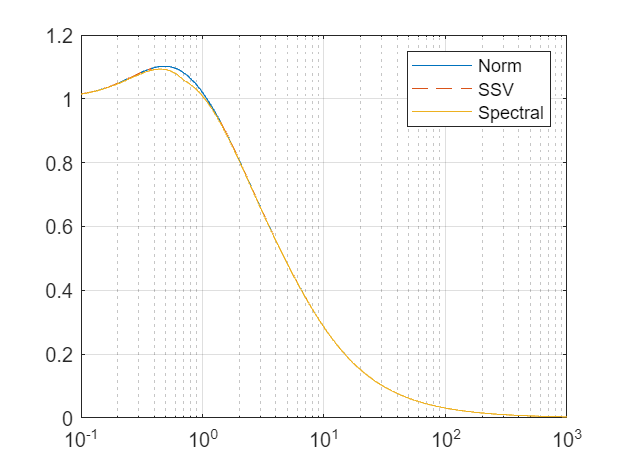


[VDelta,VSigma,VLmi] = mussvextract(muinfo);
VDelta.responsedata(:,:,:);
upperBound = bounds(1).ResponseData(:);

figure()
semilogx(W,max(SV),W,upperBound,'--',W,spectral)
% ylim([0;4])
legend('Norm', 'SSV', 'Spectral')
grid on

set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
% saveas(gcf,'../Images/SSV_PLOT_Procedure2','epsc')

% H = [An, B*B'; -(K*eye(12))'*(K*eye(12)), -An']

% W = logspace(-1,3,100);
% Ms = freqresp(Mn2,W);
% yalmip('clear')
% gamma = 0.01;
% % D = sdpvar(4,4,'symmetric','complex');
% % Q = D*D'
% D = sdpvar(4,4,'toeplitz','complex');
% Q = D-diag(imag(diag(D)))*sqrt(-1)
% constraints = [Ms(40)*Q*Ms(40)' <= gamma^2*Q, Q>=0]
% options = sdpsettings('verbose',0,'solver','mosek');
% sol = optimize(constraints,[],options)
% value(Q)
% eig(value(Q))


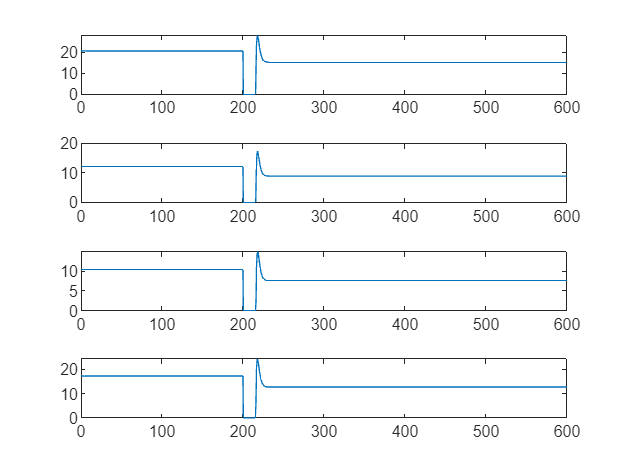

figure()
tiledlayout('vertical')
for i=1:4
    x0 = [param.ctrl.T_wOP(i); param.ctrl.T_aOP(i); 0];
    [t,x] = ode23s(@(t,x)model.decoupledDynamics(t,x,i,param,200),[0 simtime],x0);
    decoupledResults(i).time = t;
    decoupledResults(i).Tw = x(:,1);
    decoupledResults(i).Ta = x(:,2);
    decoupledResults(i).T = x(:,3);

    q = zeros(1,length(t));
      for k=1:length(t)
        [~,q(k)] = model.decoupledDynamics(t(k),x(k,:)',i,param);
      end
      nexttile
      plot(t,q*3600)
end

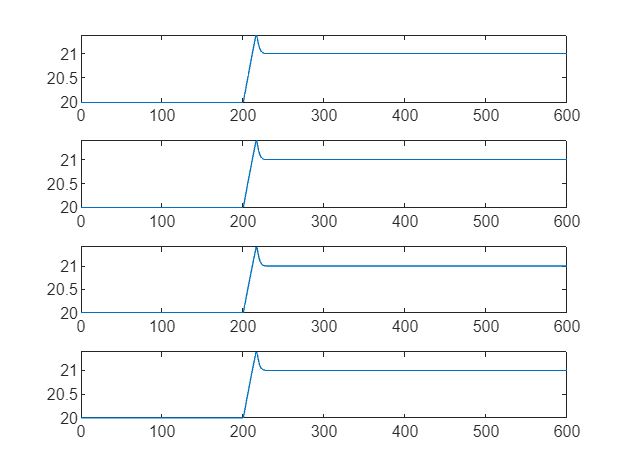



figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(decoupledResults(i).time,decoupledResults(i).Ta-273.15)
end

x0 = [param.ctrl.T_wOP.'; param.ctrl.T_aOP.'; zeros(4,1)];
% options = odeset('RelTol',1e-8,'AbsTol',1e-10);
[t,x] = ode23s(@(t,x)model.coupledDynamics(t,x,param,200),[0 simtime],x0);

-16.008405, -40.669186, -91.594605, 0.000000, 


0.000000, 0.000000, 0.000000, -2.355647, 


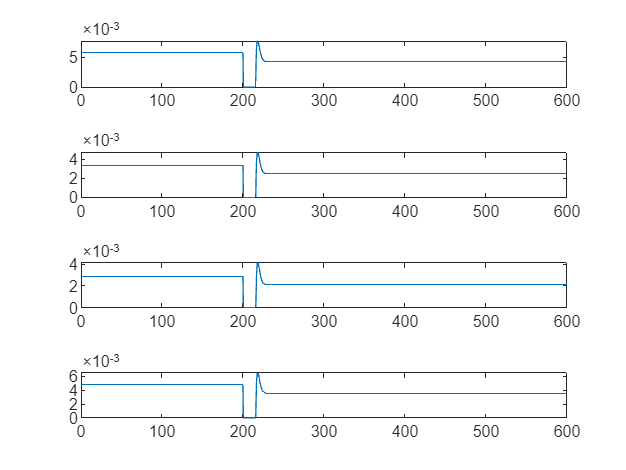

coupledResults.time = t;
coupledResults.Tw = x(:,1:4);
coupledResults.Ta = x(:,5:8);
coupledResults.T = x(:,9:12);

q = zeros(4,length(x(:,1)));
for k=1:length(x(:,1))
  [~,q(:,k)] = model.coupledDynamics(t(k),x(k,:)',param);
end
figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(t,q(i,:));
end

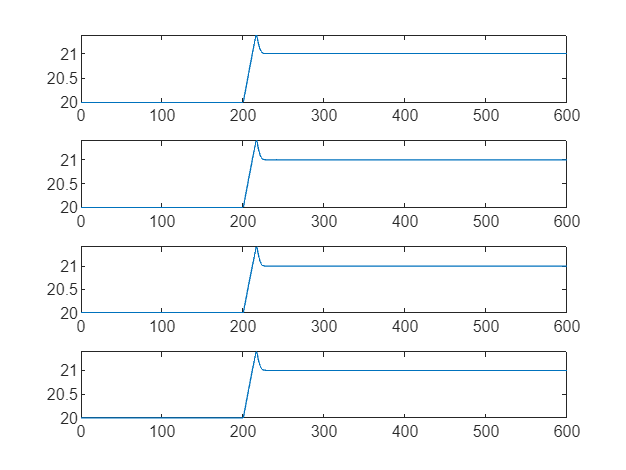



figure()
tiledlayout('vertical')

for i=1:4
    nexttile
    plot(coupledResults.time,coupledResults.Ta(:,i)-273.15)
end

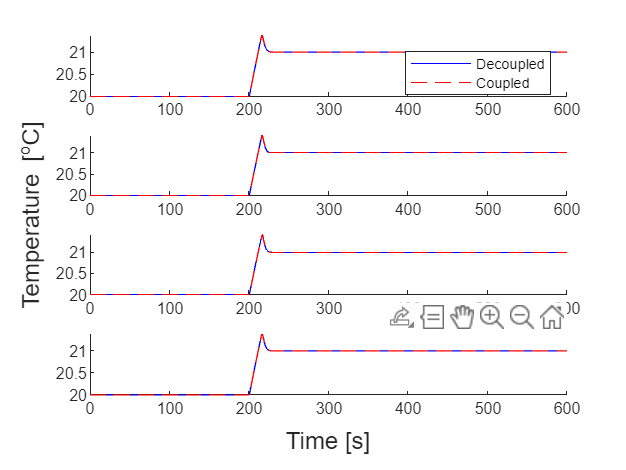

figure()
f = tiledlayout('vertical');
for i=1:4
    nexttile
    hold on
    plot(decoupledResults(i).time,decoupledResults(i).Ta-273.15,'blue')
    plot(coupledResults.time,coupledResults.Ta(:,i)-273.15,['red','--'])
    if i==1
        legend('Decoupled','Coupled',Location='northeast')
    end
    hold off
end
xlabel(f,'Time [s]')
ylabel(f,'Temperature [^{o}C]')